# Laboratory 2: Translational Mechanical System Time Domain and Frequency Domain Modeling

## Instructions:

- Draw the free body diagram for the following system.

- Build a two degrees of freedom mechanical system using Simulink as shown below. Note that the system contains two masses m1 and m2, two springs with spring constants k1 and k2, and two dampers with damping coefficients b1 and b2. 

                  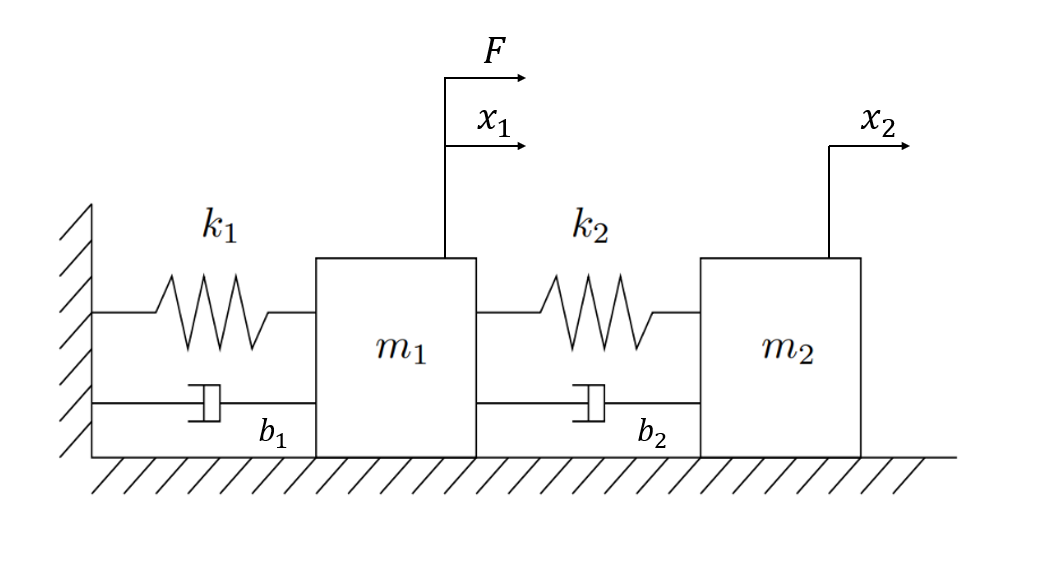

        3. Assuming m1 = 1 Kg, b1 = 1 Ns/m, k1 = 1 N/m, m2 = 1 Kg, b2 = 1 Ns/m, k2 = 1 N/m, apply a unit step input F and simulate the system. 

        4. Plot the displacement x1, x2, and Force (input) on one graph.

        5. Assume that the system has no damping element, simulate the system. 

## Part 1: Time Domain Modeling

**Task 1: Understand the Project Scope**

System modeling is used to map the reality (real dynamic system such as a car) into a set of simplified mathematical equations (model).

A system model is a set of governing mathematical equations which describe the model's dynamical behavior.

Once you have a governing mathematical equations, you can then simulate the system and assess its performance using simulation tools such as Matlab/Simulink.

As a rule of thumb, we keep the model simple at first and add complexity as needed later on!

The dynamics of many systems, whether they are mechanical, electrical, thermal, economic, etc., may be described in terms of differential equations. Such differential equations may be obtained by using physical laws such as Newton's laws for mechanical systems or Kirchhoff's laws for electrical systems. 

Consider a simple mass spring damper system as shown below:

               Assume M1 = 1 Kg, b1 = 1 Ns/m, k1 = 1 N/m, M2 = 1 Kg, b2 = 1 Ns/m, k2 = 1 N/m

**Task 2: Draw the Free Body Diagram and Derive Mathematical Equations**

Let's draw the free body diagram of the system, The Force F is the input to the system and displacement x is the output.

The spring force is directly proportianal to the displacement $x$ while the viscous damping force is directly proportional to the velocity $\dot{x}$.

Using Newton's Second law of motion, the system can be described by the following equations:

                                                                    
$$M\ddot{x} =F-b\dot{x} -\textrm{kx}$$


                                                                  
$$ẍ=\mathrm{M2}\left(F-bẋ-kx\right)$$


FBD 1:

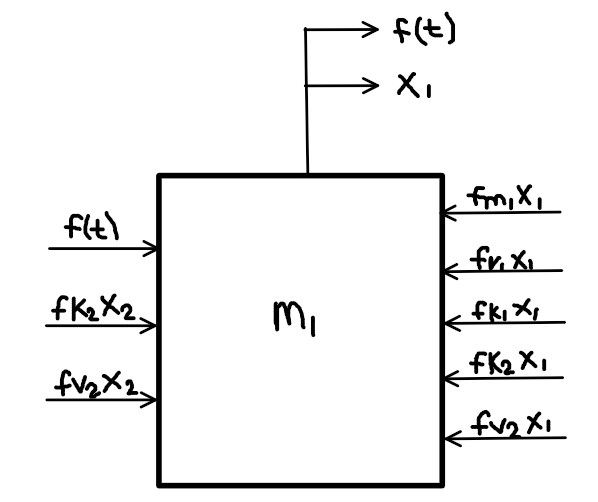


$$f\left(t\right)=fm_1 x_1 +fk_1 x_1 +fv_1 x_1 +fk_2 x_2 +fv_2 x_1 -fk_2 -fv_2 x_2$$



$$f\left(t\right)=m_1 {\overset{\ldotp \ldotp }{x} }_1 +k_1 x_1 +v_1 x_1 +k_2 x_2 +v_2 x_1 -k_2 x_2 -v_2 x_2$$


${\overset{\ldotp \ldotp }{x} }_1 =\frac{1}{m_1 }{\left\lbrack f\left(t\right)-B_1 x_1 -k_1 x_1 -B_2 \left({\overset{\ldotp }{x} }_1 -{\overset{\ldotp }{x} }_2 \right)-k_2 \left({-x}_2 +x_1 \right)\right\rbrack }$(eq. 1)

FBD 2:

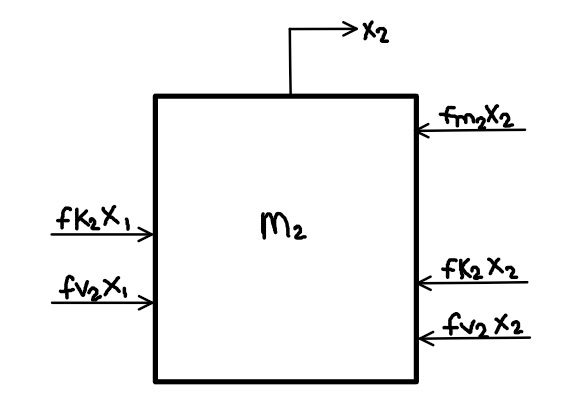


$$0=fm_2 x_2 +fk_2 x_2 +fv_2 x_2 -fk_2 x_1 -fv_2 x_1$$



$$0=m_2 {\overset{\ldotp \ldotp }{x} }_2 +k_2 x_2 +B_2 x_2 -k_2 x_1 -B_2 x_1$$


${\overset{\ldotp \ldotp }{x} }_2 =\frac{1}{m_2 }\left\lbrack k_2 \left(x_1 -x_2 \right)+B_2 \left({\overset{\ldotp }{x} }_1 -{\overset{\ldotp }{x} }_2 \right)\right\rbrack$ (eq. 2)

**Task 3: Build Simulink Model **

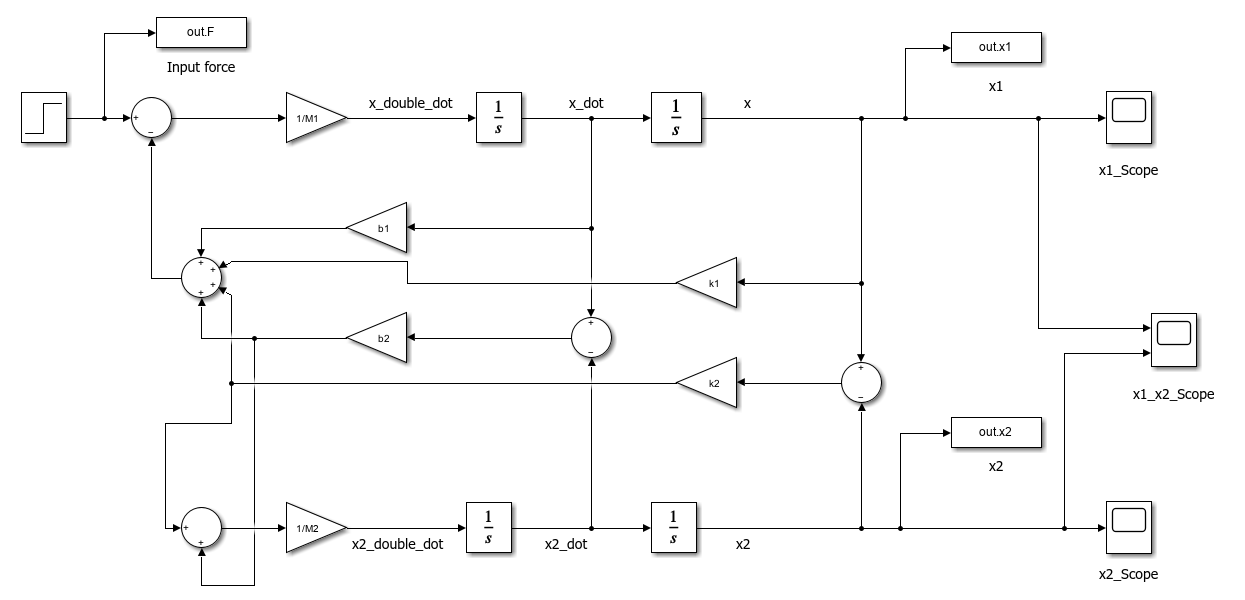

**Task 4: Simulate the Model**

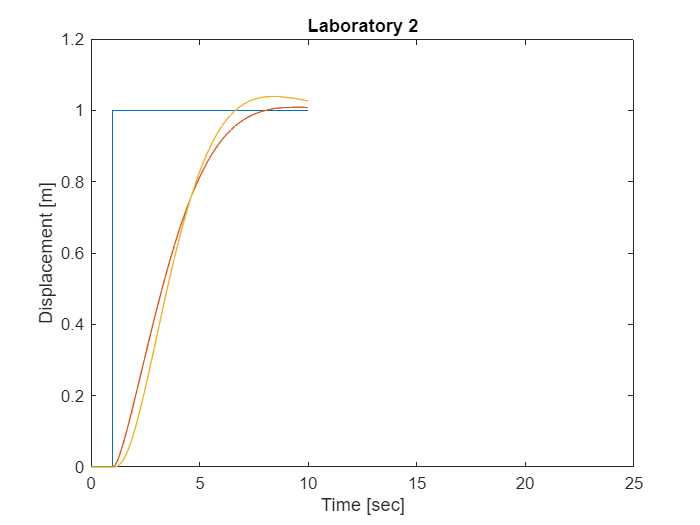

% Define Model Parameters
Sim_Time = 25;
F = 1 ;
M1 = 1;
b1 = 2.5;
k1 = 1;

M2 = 1;
b2 = 1.9;
k2 = 1;
sim('Laboratory_2_simulink');
figure %for figure plotting of the model
plot(ans.F) 
hold on 
plot(ans.x1) 
hold on 
plot(ans.x2) 
hold on
ylabel('Displacement [m]')
xlabel('Time [sec]')
title('Laboratory 2')

xlim([0 25])
ylim([0 1.2])

## Part 2: Frequency Domain - Transfer Function Modeling